#### Loading the Trained Random Forest Model

predNBLoad=load('finalModelNB.mat')

predNBLoad = struct with fields:
           XTest: [1527×42 table]
    finalModelNB: [1×1 ClassificationNaiveBayes]
           yTest: [1527×1 table]


predNB= predict(predNBLoad.finalModelNB,predNBLoad.XTest)

predNB =      0
     0
     0
     0
     0
     0
     0
     0
     1
     0


#### Plotting Confusion Matrix

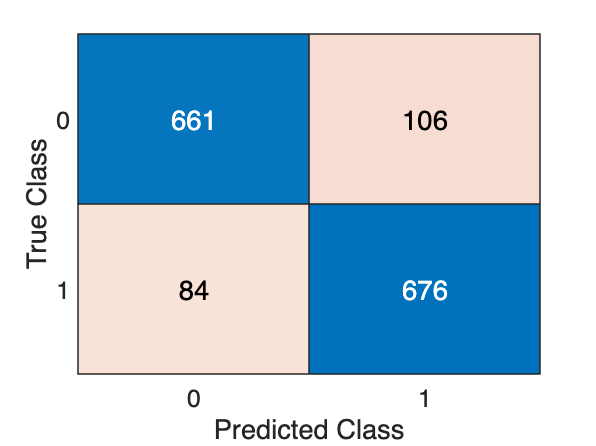

cm = confusionchart(table2array(predNBLoad.yTest),predNB);

#### Precision

cmatrixNB= confusionmat(table2array(predNBLoad.yTest),predNB) 

cmatrixNB =    661   106
    84   676



precisionNB =  diag(cmatrixNB)./sum(cmatrixNB,2)

precisionNB =     0.8618
    0.8895


overAllPrecNB= mean(precisionNB)

overAllPrecNB = 0.8756

#### Recall


recallNB =  diag(cmatrixNB)./sum(cmatrixNB,1)';
overAllRecNB= mean(recallNB)

overAllRecNB = 0.8758

#### F1 Score

f1ScoreNB = 2*(overAllPrecNB.*overAllRecNB)./(overAllPrecNB+overAllRecNB)

f1ScoreNB = 0.8757

[~,Scores] = predict(predNBLoad.finalModelNB,predNBLoad.XTest)

Scores =     1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    0.0000    1.0000
    0.9065    0.0935


classNamesBankData=predNBLoad.finalModelNB.ClassNames

classNamesBankData =      0
     1


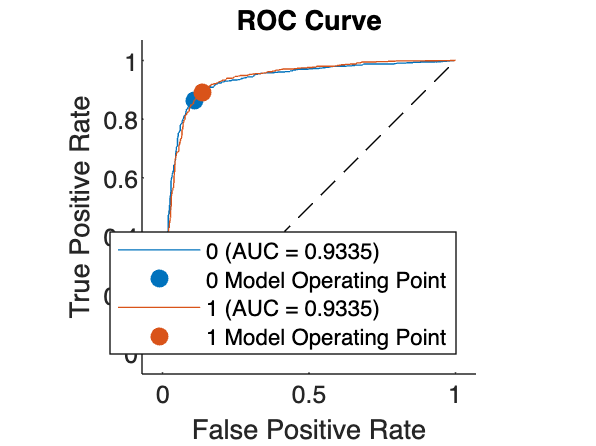


rocObj = rocmetrics(table2array(predNBLoad.yTest),Scores,classNamesBankData);
plot(rocObj)